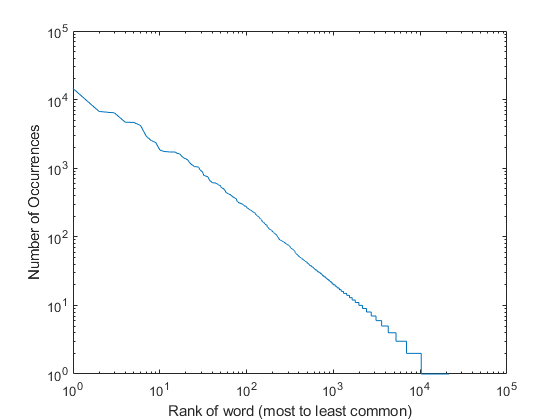

ans = 10×4 table
    Words     NumOccurrences    PercentOfText    CumulativePercentOfText
    ______    ______________    _____________    _______________________

    "the"         14500             6.6489               6.6489         
    "of"           6711             3.0773               9.7262         
    "and"          6406             2.9374               12.664         
    "a"            4677             2.1446               14.808         
    "to"           4658             2.1359               16.944         
    "in"           4183             1.9181               18.862         
    "that"         2920             1.3389               20.201         
    "his"          2519             1.1551               21.356         
    "it"           2363             1.0835                22.44         
    "i"            1842            0.84464 

clc; clear; close all;
%d) Moby-Dick - Herman Melville
zipf();

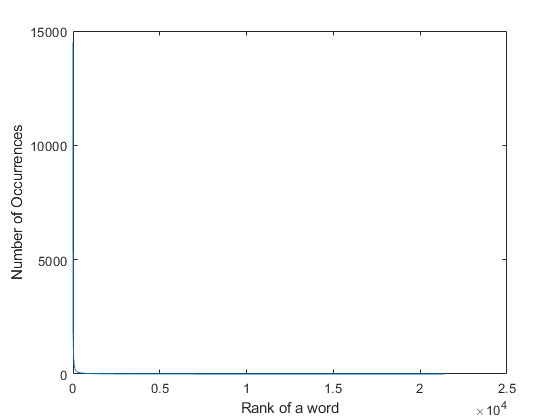

%5
plot(1:size(words), numOccurrences);
xlabel('Rank of a word');
ylabel('Number of Occurrences');

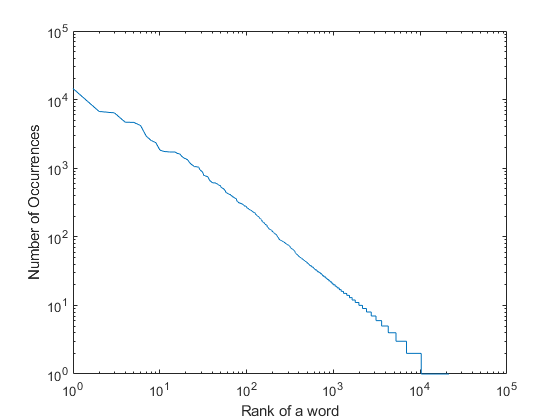

%Better Plotted on log graph
loglog(numOccurrences);
xlabel('Rank of a word');
ylabel('Number of Occurrences');

%5
%Top 10 words based on number of occurrences
words(rankIndex(1:10))

ans = 10×1 string array
    "the"
    "of"
    "and"
    "a"
    "to"
    "in"
    "that"
    "his"
    "it"
    "i"


%5
% frequency of most common word
fMostCommon = numOccurrences(1)

fMostCommon = 14500

% N = 5
f5CommonMeasured = numOccurrences(5)

f5CommonMeasured = 4658

f5CommonCalculated = fMostCommon * 1/5

f5CommonCalculated = 2900

% N = 10
f10CommonMeasured = numOccurrences(10)

f10CommonMeasured = 1842

f10CommonCalculated = fMostCommon * 1/10

f10CommonCalculated = 1450

% in this text, the frequency calculated using Zipf's Law is much closer to
% the expected values, most likely due to analysis of a larger number of
% words in the text. Additionally, of the top 10 words in this novel, 9 are
% the same as in the previous analysis. While the top 10 words are the
% same, the order of most common occurence is slightly different.